# Exam 2022

## Force field

clc;
clear;
close all;

syms x y;

goal = [1; 0];

obs1 = [1.5;0];
obs2 = [1;1];
obs3 = [1;-1];

pose = [x; y];

isCondition = 0; % If there is a condition for U change to 1

rho_goal = ((pose(1)-goal(1))^2+(pose(2)-goal(2))^2);

rho_obs1 = sqrt((pose(1)-obs1(1))^2+(pose(2)-obs1(2))^2);
rho_obs2 = sqrt((pose(1)-obs2(1))^2+(pose(2)-obs2(2))^2);
rho_obs3 = sqrt((pose(1)-obs3(1))^2+(pose(2)-obs3(2))^2);

U_attr = (1/2)*rho_goal^2;  

U_rep1 = (1/2)*((1/rho_obs1)^2);   % remove 1/2 if answer is wrong
U_rep2 =  (1/2)*((1/rho_obs2)^2);   % remove 1/2 if answer is wrong
U_rep3 =  (1/2)*((1/rho_obs3)^2);   % remove 1/2 if answer is wrong

if isCondition == 1
    U_cond = 0.5; % add condition (comment out if no condition is given)
    U_cond_val = 0; % add condition value
end

gradient_attr = [diff(U_attr,x); diff(U_attr,y)];

gradient_rep1 = [diff(U_rep1,x); diff(U_rep1,y)];
gradient_rep2 = [diff(U_rep2,x); diff(U_rep2,y)];
gradient_rep3 = [diff(U_rep3,x); diff(U_rep3,y)];


F_attr = -gradient_attr;

F_rep1 = -gradient_rep1;
F_rep2 = -gradient_rep2;
F_rep3 = -gradient_rep3;

% [f,s] = vpasolve(F_attr + F_rep1 + F_rep2 + F_rep3 == 0,[x,y]);
% s

% use equation below if there is one obstacle
eq = F_attr + F_rep1; 

% use equation below if there are two or more obstacles
% eq = F_attr + F_rep1 + F_rep2 + F_rep3;

maxIter = 1000; % Increase if robot does not converge
stepSize = 0.001; % Decrease if accuracy is too low

logf = [0,0];

vec = eval(subs(eq,{x,y},{0,0}))

vec =     1.7037
         0



pose = [0,0];  % Initial position of robot

force_at = [1,0]

force_at =      1     0



force = eval(subs(eq,{x,y},{force_at(1),force_at(2)}))

force =     -8
     0


norm(force)

ans = 8



for i = 0:(maxIter-1)
    if (isCondition == 1)
        if eval(subs(rho_obs1,{x,y},{pose(1),pose(2)})  > U_cond)
            %  Conditional only works with 1 obstacle
            vec = eval(subs(F_attr+U_cond_val,{x,y},{pose(1),pose(2)}));
        else
            vec = eval(subs(eq,{x,y},{pose(1),pose(2)}));
        end
    else
         vec = eval(subs(eq,{x,y},{pose(1),pose(2)}));
    end

    vec = vec';

    pose = pose + vec/norm(vec)*stepSize;

    logf(i+1,:) = pose;
    
    % Comment the following "if" out if the robot stops before converging.
     if (i > 3 && logf(i+1)==logf(i-1))
        disp("ROBOT CONVERGED AT: ")
        disp(logf(end:end,:))
        break
     end
end

ROBOT CONVERGED AT: 


    0.3240         0



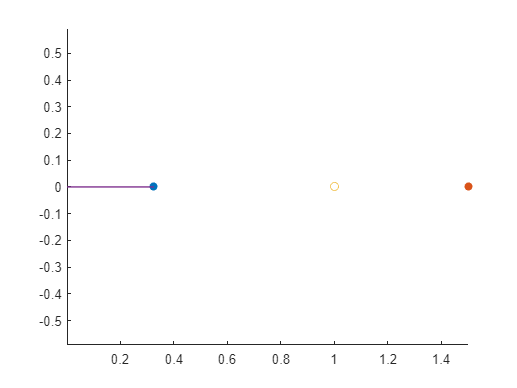


hold on
scatter(pose(1),pose(2),'filled')
scatter(obs1(1),obs1(2),'filled')
% scatter(obs2(1),obs2(2),'filled')
% scatter(obs3(1),obs3(2),'filled')

scatter(goal(1),goal(2))
plot(logf(:,1),logf(:,2))
axis equal  


logf(end-10:end,:) % write last 10 coordinate

ans =     0.3160         0
    0.3170         0
    0.3180         0
    0.3190         0
    0.3200         0
    0.3210         0
    0.3220         0
    0.3230         0
    0.3240         0
    0.3250         0
